# Parameter Fitting

Last Updated: 2021-10-24

### 1) What parameters do I need to fit?

#### All parameters:

    Cas degradation (Cas_degradation)

- Dash had a value for this- got it from fitting (Dp in his code)

- Dp was used for both complex and cas only degradation

    Cas gRNA binding (Cas_gRNA_binding)

- Dash had a value for this- got it from fitting (k1 in his code)

    Activation coefficient for TF (K_A)

-     Not sure how/if Dash got the value?

    Protein production of Cas 9 (alpha_p Cas 9)

- Dash had a value for this- got it from fitting (Tc in his code)

- Was truly this, he says it is transcription and tranlation in one

    Protein production of cre (alpha_p cre)

-     Don't think Dash has a value, he has a steady state assumption- comment in FitSwitchOnWithRepression: "Cre recombinase is in steady state since it's enzyme and ORF is in genome."

    Protein production of TF (alpha_p TF)

-     Not sure how/if Dash got the value?

    RNA production of sgRNA1 (alpha_r sgRNA1)

- Dash got value from fitting (T1 in his code)

- Do we want to be variable?

    RNA production of sgRNA2 (alpha_r sgRNA2)

- I think Dash was assuming ass gRNAs have same production rate

    Degradation of unbound cas 9 (delta cas 9)

- Dash had a value for this- got it from fitting (Dp in his code)

    Degradation of cre (delta cre)

- Did Dash's steady state assumption remove this as well?

    Degradation of unbound sgRNAs (delta g)

- Dash got value from fitting (Dr in his code)

    Cas editing rate (k_cat)

- I think Dash got the value from fitting (k2 and Km2?)

    Cre complex cutting rate (k_cre)

- I think Dash got the value from fitting (CreC? k3 and Km3?)

    Hill coefficient (n)

- Not sure what Dash was using

#### What can I re-use from Dash:

Dash notes there was a mistake in the initial conditions of FitCas9AssumeDelay and says that all parameters need to be refit

#### What can I pull from the literature:

Calin Belta paper values (Specifically from SI table 2, row LmrA)

Activation coefficient for TF (K_A)

- Called d in the paper

- Value: 2.34 * 10^6

- Error: 0.020

Hill coefficinet (n)

- Called h in the paper

- Value: 0.92

- Error: 0.020

Use these as initial values, but can be modulatable.

#### What needs to be fit:

Protein degradation

- Cas degradation (Cas_degradation)

- Degradation of unbound cas 9 (delta cas 9)

- Degradation of cre (delta cre)

Cre complex cutting rate (k_cre)

Cas editing rate (k_cat)

Cas gRNA binding (Cas_gRNA_binding)

Degradation of unbound sgRNAs (delta g)

Get first values from Chylinski, but can be variable

- Protein production of Cas 9 (alpha_p Cas 9)

- Protein production of cre (alpha_p cre)

- Protein production of TF (alpha_p TF)

- RNA production of sgRNA1 (alpha_r sgRNA1)

- RNA production of sgRNA2 (alpha_r sgRNA2)

### 2) What data do I have?

Spreadsheet from Chylinski et al 2019 (https://static-content.springer.com/esm/art%3A10.1038%2Fs41467-019-13403-y/MediaObjects/41467_2019_13403_MOESM1_ESM.pdf)

Because the spreadsheet is a difficult to read in, I retyped the numbers into a .m file (chylinski_data.m)

- Want to double check that all the numbers are typed correctly

### 3) Fitting

I used the data shown in figure one (cre turning on sgRNA that targets GFP expression)- looking at "switch-ON" for the Cre+ run (fig 1 c) 

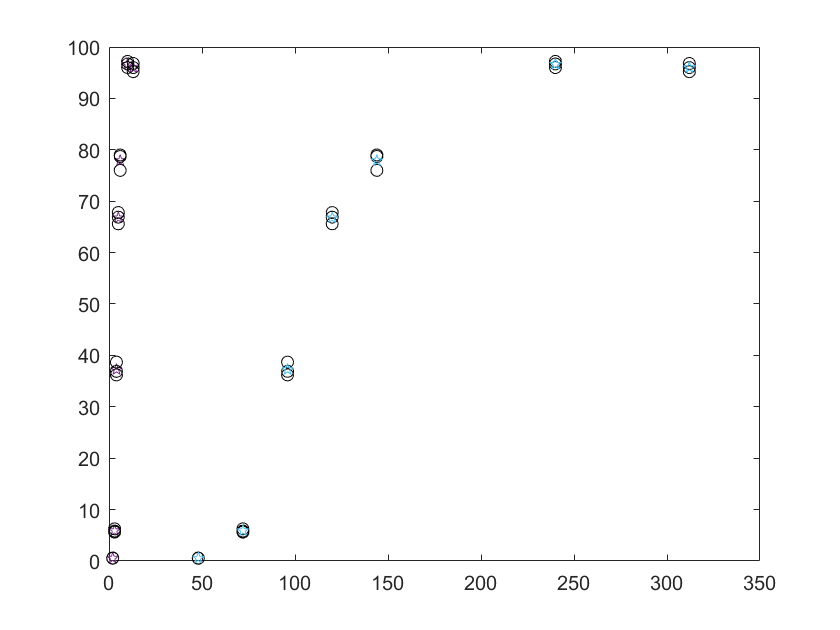

% Hardcode the data
xFig1 = [2 2 2 3 3 3 4 4 4 5 5 5 6 6 6 10 10 10 13 13 13];
yFig1 = [0.53 0.54, 0.59 5.62 5.83 6.26 36.9 36.2 38.7 67.8 65.6 66.9 79 76 78.7 96 97.2 96.7 95.2 96.8 96];
% Get the average for each unique time point
[G, days] = findgroups(xFig1);
yMeansFig1 = splitapply(@mean, yFig1, G);
% Convert to hours
hours = days .* 24;

% Plot just to check the data (i.e. for typos)
plot(xFig1.*24, yFig1, 'ko')
hold on;
plot(hours, yMeansFig1, 'p')

% No idea why I am getting 2 sets of dots...

% Create the model, see the end of the file

% Fit the model using a starting point: Not sure what values to use
parameters0 = [1 1 1 1 1 1 1];
x = lsqcurvefit(@fit_Cre_on_Kill_Switch, parameters0, hours, yMeansFig1)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    -3.1421    7.1895   -1.7143    2.8671    0.9216   -1.0083   -4.4443


% Plot the function on top of the data
res = fit_Cre_on_Kill_Switch(x, [0 312])

res =     1.0000    0.9559    0.9130    0.8711    0.8302    0.6399    0.4708    0.3195    0.1832    0.0554   -0.0616   -0.1700   -0.2721   -0.3658   -0.4576   -0.5496   -0.6445   -0.7139   -0.7878   -0.8683   -0.9585   -1.0192   -1.0863   -1.1621   -1.2497   -1.3105   -1.3787   -1.4568   -1.5480   -1.6108   -1.6815   -1.7626   -1.8574   -1.9232   -1.9974   -2.0824   -2.1819   -2.2500   -2.3266   -2.4143   -2.5166   -2.5870   -2.6663   -2.7568   -2.8623   -2.9341   -3.0147   -3.1066   -3.2135   -3.2868


plot(xFig1.*24, yFig1, 'ko')

function yResults = fit_Cre_on_Kill_Switch(parameters, t)

    % Intial values (Same number of elements as x in the DiffEq function)
    y0=ones(1, 10); % Set everything to 1?
    
    % Run ODE
    [T, Cv] = ode45(@diff_eq, t, y0); % Cv is a name I got from a function on stack exchange, change it?
    
    % ODE differential function
    function dx=diff_eq(t, x)
        % lsqcurve fit won't let me pass x0 as a map, only as a double
    	alpha_p_Cre = parameters(1);
        alpha_p_Cas9 = parameters(1);
        alpha_p_GFP = parameters(1);
        
    	delta_Cre = parameters(2);
        delta_Cas9 = parameters(2);
        delta_GFP = parameters(2);
        Cas_degradation = parameters(2);
        
        alpha_r_sgRNA1 = parameters(3);
        delta_g = parameters(4);
        
    	k_cre = parameters(5);
        Cas_gRNA_binding = parameters(6);
        k_cat = parameters(7);       
        
        % Unpack individual species from x
        AAV = x(1);
    	Cas9 = x(2);
    	Cas9_sgRNA1 = x(3);
    	Cre = x(4);
    	Cre_regulated_region = x(5);
    	edited_Cre_regulated_region = x(6);
    	postedit_Cas9_sgRNA1 = x(7);
    	sgRNA1 = x(8);
        % Add GFP
        gfpGene = x(9);
        gfp = x(10);
        
        % Compute derivative for each species
        % Nothing is targting AAV genome
        d_AAV = 0; % Does this need a different name? 
        % Cre gets expressed, degrades
        d_Cre =  alpha_p_Cre*AAV - delta_Cre*Cre;
        % Cas gets expressed, binds, degrades
        d_Cas9 =  alpha_p_Cas9*AAV - Cas_gRNA_binding*Cas9*sgRNA1 - ...
            delta_Cas9*Cas9;
        % Cre modifies the genome
        d_Cre_regulated_region = - k_cre*Cre_regulated_region*Cre^4 + ...
            (Cre_regulated_region/AAV)*d_AAV;
    	d_edited_Cre_regulated_region =  k_cre*Cre_regulated_region*Cre^4 + ...
            (edited_Cre_regulated_region/AAV)*d_AAV;
        % sgRNA is expressed
        d_sgRNA1 =  alpha_r_sgRNA1*(edited_Cre_regulated_region/AAV)*AAV - ...
            Cas_gRNA_binding*Cas9*sgRNA1 - delta_g*sgRNA1;
        % sgRNA binds to Cas and edits  
    	d_Cas9_sgRNA1 =  Cas_gRNA_binding*Cas9*sgRNA1 - ...
            Cas_degradation*Cas9_sgRNA1 - k_cat*gfpGene*Cas9_sgRNA1;
        d_postedit_Cas9_sgRNA1 =  k_cat*gfpGene*Cas9_sgRNA1 - ...
            Cas_degradation*postedit_Cas9_sgRNA1;
        % gfp has its own gene
        d_gfpGene = -k_cat*gfpGene*Cas9_sgRNA1;
        % gfp gets expressed
        d_gfp = alpha_p_GFP*gfpGene - delta_GFP*gfp;
    
        % Pack derivatives for return
        dx = [d_AAV, d_Cas9, d_Cas9_sgRNA1, d_Cre, d_Cre_regulated_region, ...
            d_edited_Cre_regulated_region, d_postedit_Cas9_sgRNA1, d_sgRNA1, d_gfpGene, d_gfp]';
    end
    
    
    % Solve for just the percent of GFP (what the paper is reporting)
    yResults = (Cv(:, 10) / 1)'; % Change 1 to be the original amount
end


% Function for the plotting of the results
function [time_interval, y_out, y] = Cre_on_Kill_Switch(time_span, parameters, initial, step)
% time_span is the hours values [start, stop]
% parameters is a Map of names to numbers (e.g., rate constants, decay rates, Hill coefficients)
% initial is a Map of variable names to initial values
% step is the number of hours between samples in output; defaults to 1
% Returns vector of time, matrix of output levels at those time points, matrix of all species
    if nargin < 4, step = 1; end
    
    % Define names for input/output variable indexes
    AAV = 1;
	Cre_regulated_region = 6;
	genome = 9; % Not here anymore

    % Set initial values
    y0=zeros(1,13);
    y0(AAV) = initial('AAV');
	y0(Cre_regulated_region) = initial('Cre_regulated_region');
	y0(genome) = initial('genome'); % Not here anymore
    
    % Run ODE
    solution = ode45(@(t,x) diff_eq(t, x, parameters), time_span, y0);
    
    % Evaluate species levels at given times
    time_interval = time_span(1):step:time_span(end);
    y = deval(solution, time_interval);
    initial_gfp = 1; % Change this???
    y_out = y([gfp],:) / initial_gfp; % Change this?
end

% ODE differential function
function dx=diff_eq(t, x, parameters)
    % Unpack parameters from parameter map
    Cas_degradation = parameters('Cas_degradation');
	Cas_gRNA_binding = parameters('Cas_gRNA_binding');
	alpha_p_Cas9 = parameters('alpha_p_Cas9');
	alpha_p_Cre = parameters('alpha_p_Cre');
	alpha_r_sgRNA1 = parameters('alpha_r_sgRNA1');
	delta_Cas9 = parameters('delta_Cas9');
	delta_Cre = parameters('delta_Cre');
	delta_g = parameters('delta_g');
	k_cat = parameters('k_cat');
	k_cre = parameters('k_cre');
    alpha_p_GFP = parameters('alpha_p_GFP');
    delta_GFP = parameters('delta_GFP');
    
    % Unpack individual species from x
    AAV = x(1);
	Cas9 = x(2);
	Cas9_sgRNA1 = x(3);
	Cre = x(4);
	Cre_regulated_region = x(5);
	edited_Cre_regulated_region = x(6);
	postedit_Cas9_sgRNA1 = x(7);
	sgRNA1 = x(8);
    % Add GFP
    gfpGene = x(9);
    gfp = x(10);
    
    % Compute derivative for each species
    % Nothing is targting AAV genome
    d_AAV = 0; % Does this need a different name? 
    % Cre gets expressed, degrades
    d_Cre =  alpha_p_Cre*AAV - delta_Cre*Cre;
    % Cas gets expressed, binds, degrades
    d_Cas9 =  alpha_p_Cas9*AAV - Cas_gRNA_binding*Cas9*sgRNA1 - ...
        delta_Cas9*Cas9;
    % Cre modifies the genome
    d_Cre_regulated_region = - k_cre*Cre_regulated_region*Cre^4 + ...
        (Cre_regulated_region/AAV)*d_AAV;
	d_edited_Cre_regulated_region =  k_cre*Cre_regulated_region*Cre^4 + ...
        (edited_Cre_regulated_region/AAV)*d_AAV;
    % sgRNA is expressed
    d_sgRNA1 =  alpha_r_sgRNA1*(edited_Cre_regulated_region/AAV)*AAV - ...
        Cas_gRNA_binding*Cas9*sgRNA1 - delta_g*sgRNA1;
    % sgRNA binds to Cas and edits  
	d_Cas9_sgRNA1 =  Cas_gRNA_binding*Cas9*sgRNA1 - ...
        Cas_degradation*Cas9_sgRNA1 - k_cat*gfpGene*Cas9_sgRNA1;
    d_postedit_Cas9_sgRNA1 =  k_cat*gfpGene*Cas9_sgRNA1 - ...
        Cas_degradation*postedit_Cas9_sgRNA1;
    % gfp has its own gene
    d_gfpGene = -k_cat*gfpGene*Cas9_sgRNA1;
    % gfp gets expressed
    d_gfp = alpha_p_GFP*gfpGene - delta_GFP*gfp;

    % Pack derivatives for return
    dx = [d_AAV, d_Cas9, d_Cas9_sgRNA1, d_Cre, d_Cre_regulated_region, ...
        d_edited_Cre_regulated_region, d_postedit_Cas9_sgRNA1, d_sgRNA1, d_gfpGene, d_gfp]';
end